clc; clear all; close all;
img_path = fullfile('Brightest_Region_G','Brightest_region_86_opcionDobles_Y_segundoUmbral','z'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);
Template=double(imread('Template1.jpg'));

margen=501;%este es el tamaño de las ventanas que se van a usar, tiene que coincidir con el tamaño de las plantillas

tR=0.5;
tG=2;
tB=1;

se = strel('disk',100);

fr=5;%factor de reducción
margen=floor(501/fr/2);

%indices = find(T.quality == 4);

%for u = 1:height(T)
    k=96

k = 96


% Leer la imagen original
image = imread(string(fullfile(img_path, T{k,1})));

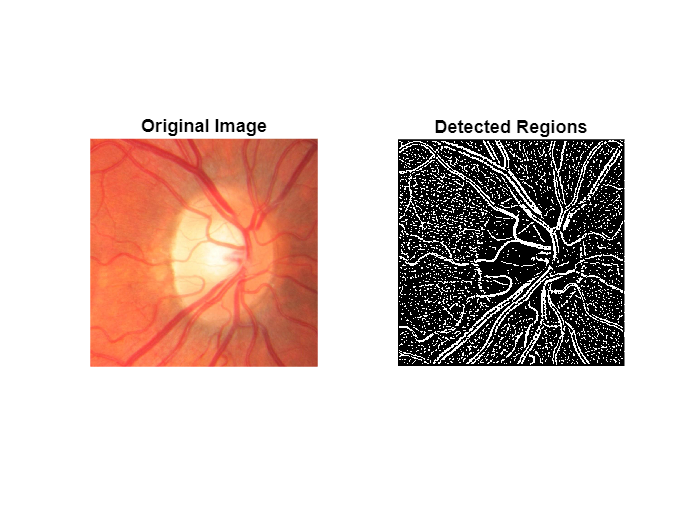



% Step 2: Convert to grayscale
grayImage = rgb2gray(image);

% Step 3: Apply GLoG filter
filterSize = 100; % Adjust the filter size as needed
sigma = 1.5; % Adjust the sigma value as needed
filter = fspecial('log', filterSize, sigma);
grayImage = imresize(grayImage, [NaN, 600], 'bicubic');
filteredImage = imfilter(grayImage, filter, 'same');

% Step 4: Threshold the filtered image
threshold = 0.5; % Adjust the threshold value as needed
binaryImage = filteredImage > threshold;
% Step 5: Display the results
figure;
subplot(1, 2, 1);
imshow(image);
title('Original Image');
subplot(1, 2, 2);
imshow(binaryImage);
title('Detected Regions');

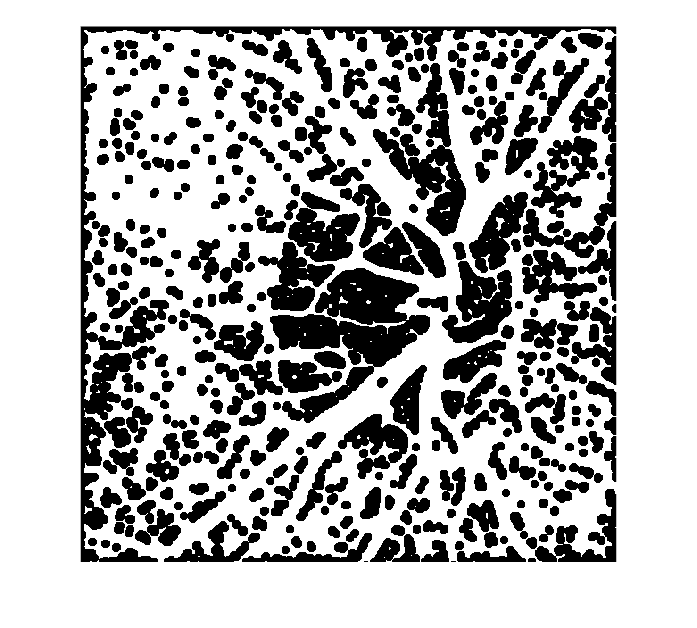



binaryImage=imclose(binaryImage, strel('disk',5));
binaryImage=imclose(binaryImage, strel('disk',3));
figure;
imshow(binaryImage,[]);

RGB=image;
I  = im2gray(RGB);%Dimentsio bakar batekoa izateko
BW = binaryImage;
[H,theta,rho] = hough(BW);

T=theta;
R=rho;

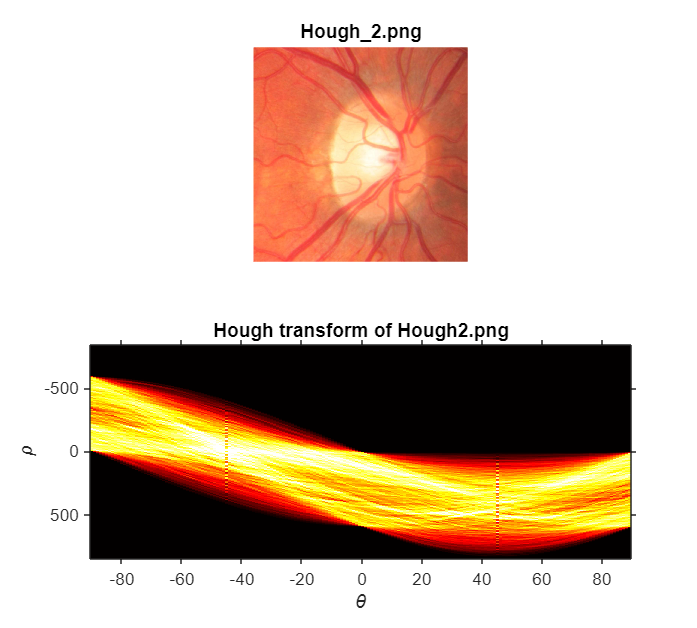

subplot(2,1,1);
imshow(RGB);
title('Hough\_2.png');
subplot(2,1,2);
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
      'InitialMagnification','fit');
title('Hough transform of Hough2.png');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
colormap(gca,hot);

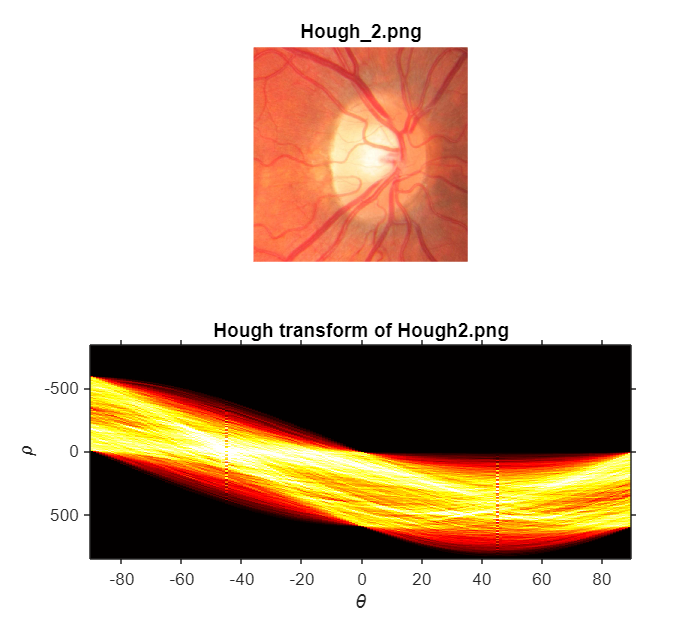

P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');

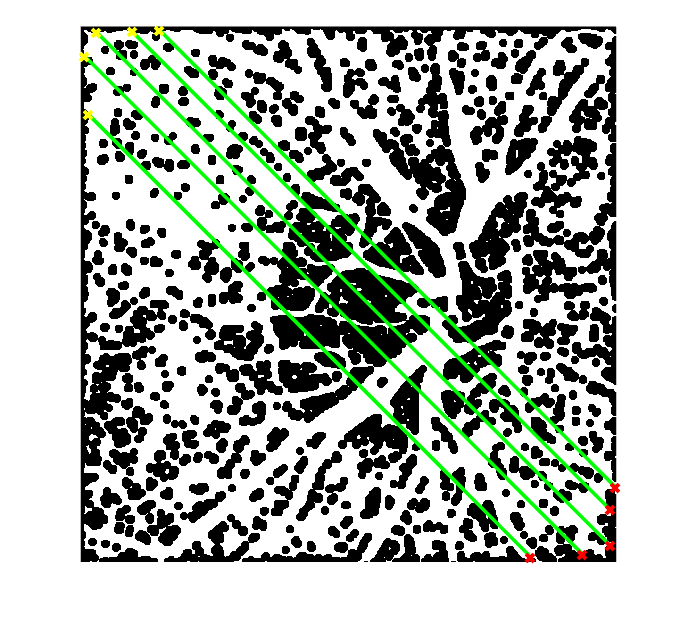

lines = houghlines(BW,T,R,P,'FillGap',600,'MinLength',10);
figure;
imshow(BW); 
hold on;
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end

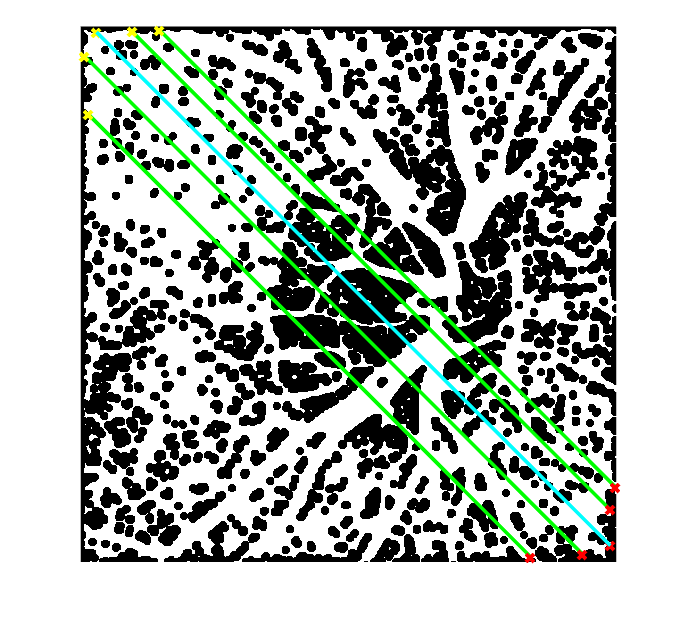

%para poner la línea más larga de cián
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','cyan');

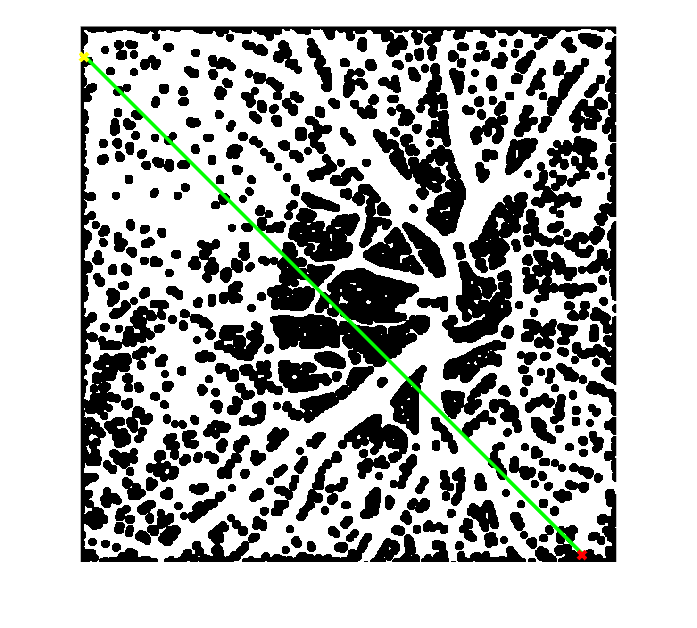

lines = houghlines(BW,T,R,P,'FillGap',600,'MinLength',10);
[~, minIndex] = min(abs([lines.theta]));
lines = lines(minIndex);
colCentroid=round([lines.point1(1)]+([lines.point1(1)]-[lines.point2(1)])/2);

figure;
imshow(BW); 
hold on;
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end